# Feed forward neural networks

## 2 layers

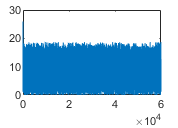

size = 30;
nb_samples = 50;

X = rand(nb_samples, size);
Y = max(X);
W = rand(size, 1);
iterations = 60000;
errors = zeros(iterations, 1);

for iter=1:iterations
    Y_ = forward_prop_linear(X, W);
    error = Y - Y_;
    delta = backward_prop_linear(error, Y_);
    errors(iter) = abs(sum(error, 'all'));
    W = W + X' * delta;
end

plot(errors)

## 3 layers

first_layer_size = 30;
second_layer_size = 15;
nb_samples = 50;

% Input of the neural network
X = rand(nb_samples, first_layer_size);

% Correct output of the neural network
Y = max(X')';

% X = [0 0 1; 0 1 1; 1 0 1; 1 1 1; 1 1 0];
% Y = [0;1;1;0;1];

% First weight matrix
W0_1 = rand(first_layer_size, second_layer_size);

% Second weight matrix
W1_2 = rand(second_layer_size, 1);

% Total number of iterations
iterations = 60000;

% Error vector for plotting
errors = zeros(iterations, 1);

for iter=1:iterations
    layer_0 = X;
    layer_1 = sigmoid(layer_0 * W0_1, 0);
    layer_2 = sigmoid(layer_1 * W1_2, 0);
    
    layer_2_error = Y - layer_2;
    layer_2_delta = layer_2_error .* sigmoid(layer_2, 1);
    
    layer_1_error = layer_2_delta * W1_2';
    layer_1_delta = layer_1_error .* sigmoid(layer_1, 1);

    W0_1 = W0_1 + X' * layer_1_delta;
    W1_2 = W1_2 + layer_1' * layer_2_delta;
    
    if(mod(iter, 10000) == 0)
        disp(mean(abs(layer_2_error)));
    end
    errors(iter, 1) = abs(sum(layer_1_error, 'all'));
    errors(iter, 2) = abs(sum(layer_2_error, 'all'));
end

    0.0082

    0.0061

    0.0063

    0.0055

    0.0070

    0.0066



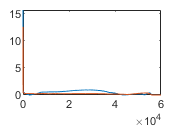


plot(errors)